# Marginal cost data regression using polyfit function

## Load cleaned marginal cost data

load("cleanedQMCTables.mat");

## Fit polynomial relation of marginal cost and quantity

### Fit quadratic relations

quadQMC = zeros(numSelParts, 3);
quadS = cell(numSelParts, 1);
quadMu = zeros(numSelParts, 2);
for n=1:numSelParts
    partCleanedQMCTable = selCleanedPartQMCTables{n};
    [p, S, mu] = polyfit(partCleanedQMCTable.Awarded, partCleanedQMCTable.MCMarket, 2);
    [y_fit, delta] = polyval(p, partCleanedQMCTable.Awarded, S, mu);
    selCleanedPartQMCTables{n}.MCQuadFit = y_fit;
    selCleanedPartQMCTables{n}.MCQuadDelta = delta;
    selCleanedPartQMCTables{n}.MCQuadError = selCleanedPartQMCTables{n}.MCMarket - selCleanedPartQMCTables{n}.MCQuadFit;
    quadQMC(n, :) = p;
    quadS{n} = S;
    quadMu(n, :) = mu.';
end

### Fit cubic relations

cubicQMC = zeros(numSelParts, 4);
cubicS = cell(numSelParts, 1);
cubicMu = zeros(numSelParts, 2);
for n=1:numSelParts
    partCleanedQMCTable = selCleanedPartQMCTables{n};
    [p, S, mu] = polyfit(partCleanedQMCTable.Awarded, partCleanedQMCTable.MCMarket, 3);
    [y_fit, delta] = polyval(p, partCleanedQMCTable.Awarded, S, mu);
    selCleanedPartQMCTables{n}.MCCubicFit = y_fit;
    selCleanedPartQMCTables{n}.MCCubicDelta = delta;
    selCleanedPartQMCTables{n}.MCCubicError = selCleanedPartQMCTables{n}.MCMarket - selCleanedPartQMCTables{n}.MCCubicFit;
    cubicQMC(n, :) = p;
    cubicS{n} = S;
    cubicMu(n, :) = mu.';
end

### Show fitness of the quadratic and cubic models

corrQuad = zeros(numSelParts, 1);
corrCubic = zeros(numSelParts, 1);
RMSEQuad = zeros(numSelParts, 1);
RMSECubic = zeros(numSelParts, 1);
for n=1:numSelParts
    partCleanedQMCTable = selCleanedPartQMCTables{n};
    % Calculate correlation coefficient
    quadR= corrcoef(partCleanedQMCTable.MCMarket, partCleanedQMCTable.MCQuadFit);
    cubicR = corrcoef(partCleanedQMCTable.MCMarket, partCleanedQMCTable.MCCubicFit);
    corrQuad(n)= quadR(1, 2);
    corrCubic(n) = cubicR(1, 2);
    % Calculate RMSE
    RMSEQuad(n) = sqrt(mean(partCleanedQMCTable.MCQuadError.^2));
    RMSECubic(n) = sqrt(mean(partCleanedQMCTable.MCCubicError.^2));
end
selPartCorrTable = table(selPartIDs, corrQuad, corrCubic, RMSEQuad, RMSECubic)

selPartCorrTable = 8×5 table
    selPartIDs    corrQuad    corrCubic    RMSEQuad    RMSECubic
    __________    ________    _________    ________    _________

    2.1249e+05    0.41861      0.41983      6.3307      6.3268  
    5.9198e+05    0.53968      0.53975      4.9817      4.9814  
    9.0279e+05    0.63816      0.64986      6.3867       6.305  
    5.9564e+05    0.68828      0.72846      3.7907      3.5798  
    8.7279e+05    0.28343      0.33959      4.5827      4.4947  
    9.5851e+05    0.41381      0.46948      4.3246      4.1943  
    3.2872e+05    0.46274      0.56655      4.5104      4.1926  
    7.4967e+05     0.4991      0.50227      9.0714      9.0522  


## Visualize quadratic relation

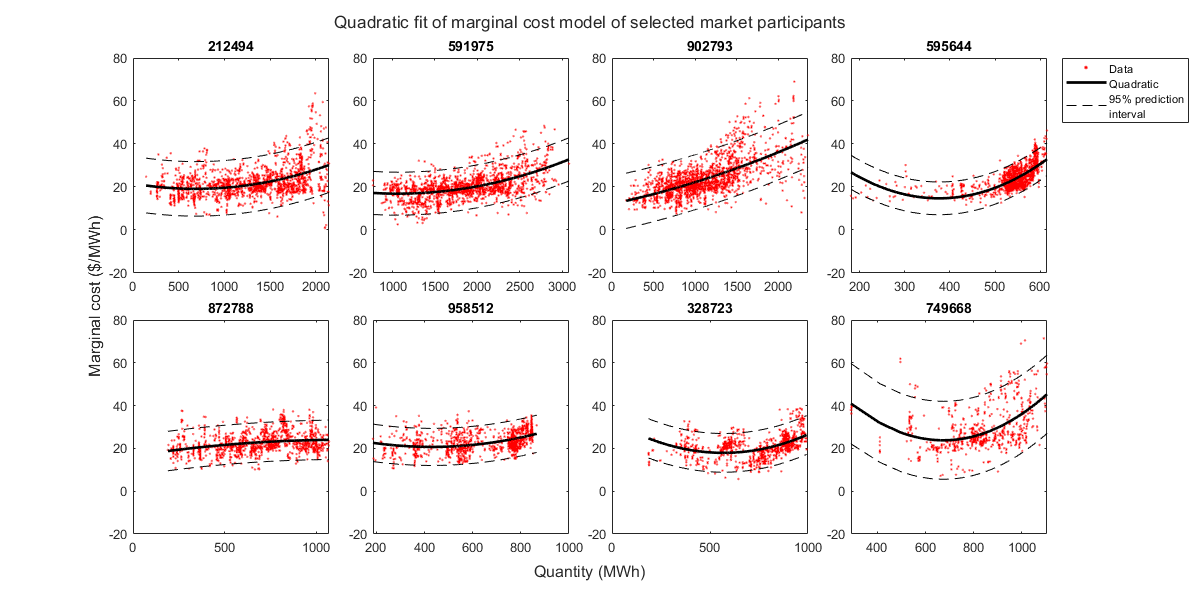

% Plot quantity vs marginal cost of selected market participants
plotColumn = 4;
t = tiledlayout(numSelParts/plotColumn, plotColumn, "TileSpacing","compact");
for n = 1:numSelParts
    nexttile;
    partCleanedQMCTable = selCleanedPartQMCTables{n};
    partID = selPartIDs(n);
    scatter(partCleanedQMCTable.Awarded, partCleanedQMCTable.MCMarket, 10, 'r.');
    hold on;
    % Plot quadratic estimation
    plot(partCleanedQMCTable.Awarded, partCleanedQMCTable.MCQuadFit, 'k-', 'Linewidth', 2);
    quadUpper = partCleanedQMCTable.MCQuadFit + 2*partCleanedQMCTable.MCQuadDelta;
    quadLower = partCleanedQMCTable.MCQuadFit - 2*partCleanedQMCTable.MCQuadDelta;
    plot(partCleanedQMCTable.Awarded, quadUpper, 'k--', partCleanedQMCTable.Awarded, quadLower,'k--');
    hold off; box on;
    title(partID);
    ylim([-20, 80]);
    if n==plotColumn
        legend(["Data", "Quadratic", "95% prediction\newlineinterval"], "Location","bestoutside");
    end
end
xlabel(t, "Quantity (MWh)");
ylabel(t, "Marginal cost ($/MWh)");
title(t, "Quadratic fit of marginal cost model of selected market participants");

set(gcf, "Position", [50, 50, 1200, 600]);

## Visualize cubic relation

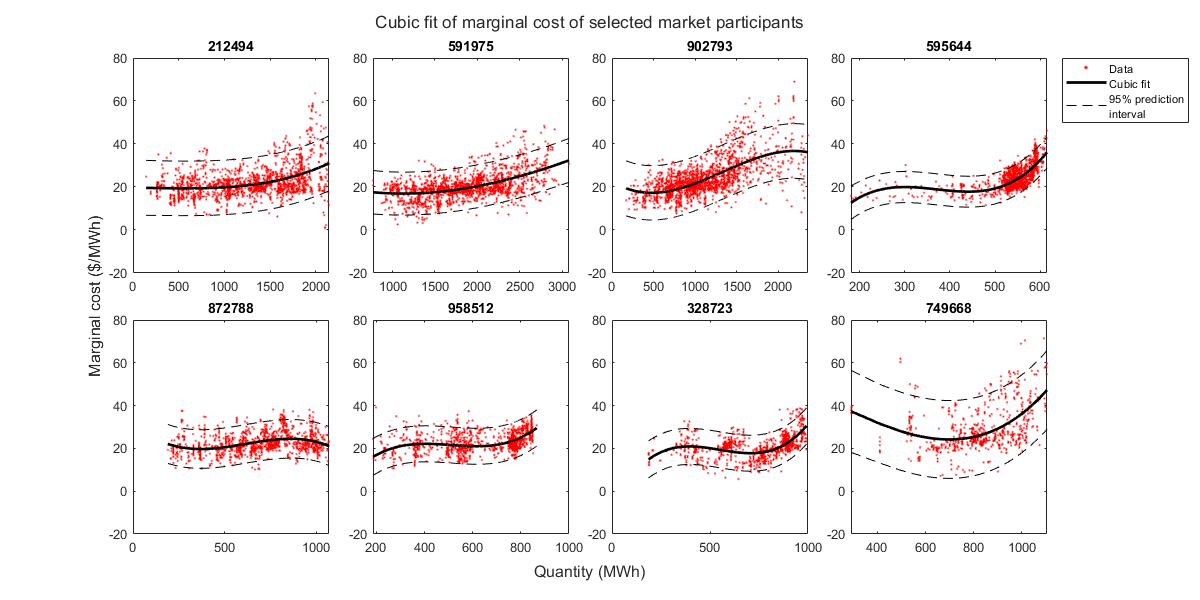

% Plot quantity vs marginal cost of selected market participants
plotColumn = 4;
t = tiledlayout(numSelParts/plotColumn, plotColumn, "TileSpacing","compact");
for n = 1:numSelParts
    nexttile;
    partCleanedQMCTable = selCleanedPartQMCTables{n};
    partID = selPartIDs(n);
    scatter(partCleanedQMCTable.Awarded, partCleanedQMCTable.MCMarket, 10, 'r.');
    hold on;
    % Plot cubic estimation
    plot(partCleanedQMCTable.Awarded, partCleanedQMCTable.MCCubicFit, 'k-', "LineWidth", 2);
    cubicUpper = partCleanedQMCTable.MCCubicFit + 2*partCleanedQMCTable.MCCubicDelta;
    cubicLower = partCleanedQMCTable.MCCubicFit - 2*partCleanedQMCTable.MCCubicDelta;
    plot(partCleanedQMCTable.Awarded, cubicUpper, 'k--', partCleanedQMCTable.Awarded, cubicLower,'k--');
    hold off; box on;
    title(partID);
    ylim([-20, 80]);
    if n==plotColumn
        legend(["Data", "Cubic fit", "95% prediction\newlineinterval"], "Location","bestoutside");
    end
end
xlabel(t, "Quantity (MWh)");
ylabel(t, "Marginal cost ($/MWh)");
title(t, "Cubic fit of marginal cost of selected market participants");

set(gcf, "Position", [50, 50, 1200, 600]);

## Write fitted models to file

save("MCRegressionQuad.mat", "quadQMC", "quadS", "quadMu", "-mat");
save("MCRegressionCubic.mat", "cubicQMC", "cubicS", "cubicMu", "-mat");
save("MCPolyfitResults.mat", "selCleanedPartQMCTables", "-mat");